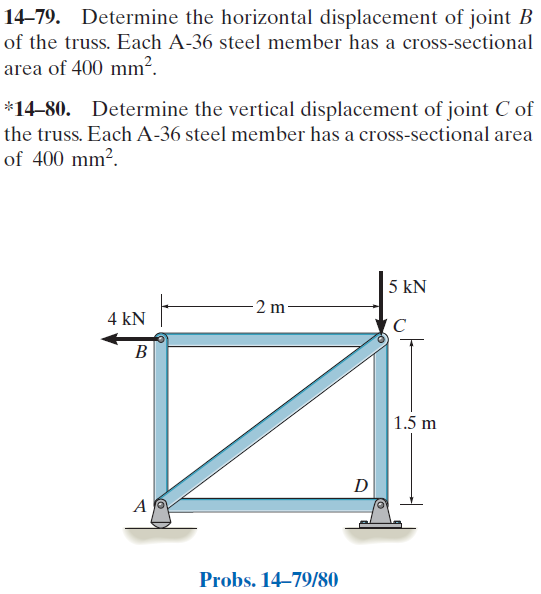

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-14-problem-79P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-14-problem-79P-solution-9780136022305) (problem 14-79)

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-14-problem-80P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-14-problem-80P-solution-9780136022305) (problem 14-80)

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# joint data

theta = atand(sym(1.5/2))*u.deg;
jointA = [0 0]*u.m;
jointB = [0 1.5]*u.m;
jointC = [2 1.5]*u.m;
jointD = [2 0]*u.m;

# member data

E = 200*u.GPa;
A = 400*u.mm^2;

# truss

t = Truss;
t = t.add('reaction', 'Ra', {0 'Ray'}, jointA);
t = t.add('reaction', 'Rd', {'Rdx' 'Rdy'}, jointD);
t = t.add('concentrated', 'Pb', [-4 0]*u.kN, jointB);
t = t.add('concentrated', 'Pc', [0 -5]*u.kN, jointC);
t = t.add('joint', 'A', jointA);
t = t.add('joint', 'B', jointB);
t = t.add('joint', 'C', jointC);
t = t.add('joint', 'D', jointD);
t = t.add('member', 'Fab', jointA, jointB, E, A);
t = t.add('member', 'Fbc', jointB, jointC, E, A);
t = t.add('member', 'Fcd', jointC, jointD, E, A);
t = t.add('member', 'Fad', jointA, jointD, E, A);
t = t.add('member', 'Fac', jointA, jointC, E, A);

# solution

[us ua ms ma ls la] = t.solve('Mode', 'factor');

# joint displacements

ua_vpa = vpa(ua, 4) %#ok<NASGU> 

$$ua\_vpa = \left(\begin{array}{cc} \mathrm{uA} & -0.1\,\mathrm{mm}\\ \mathrm{vA} & 0\\ \mathrm{uB} & -0.3672\,\mathrm{mm}\\ \mathrm{vB} & 0\\ \mathrm{uC} & -0.2672\,\mathrm{mm}\\ \mathrm{vC} & -0.0375\,\mathrm{mm}\\ \mathrm{uD} & 0\\ \mathrm{vD} & 0 \end{array}\right)$$

# forces on the truss

ma_f_m = ma.f.m %#ok<NASGU> 

$$ma\_f\_m = \left(\begin{array}{cc} \mathrm{Fab} & 0\\ \mathrm{Fbc} & 4\,\mathrm{kN}\\ \mathrm{Fcd} & -2\,\mathrm{kN}\\ \mathrm{Fad} & 4\,\mathrm{kN}\\ \mathrm{Fac} & -5\,\mathrm{kN} \end{array}\right)$$

la_f_c = la.f.c %#ok<NASGU> 

$$la\_f\_c = \left(\begin{array}{cccc} \mathrm{Ra} & 0 & 3\,\mathrm{kN} & 0\\ \mathrm{Rd} & 4\,\mathrm{kN} & 2\,\mathrm{kN} & 0\\ \mathrm{Pb} & -4\,\mathrm{kN} & 0 & 0\\ \mathrm{Pc} & 0 & -5\,\mathrm{kN} & 0 \end{array}\right)$$

ma_f_c = ma.f.c %#ok<NASGU> 

$$ma\_f\_c = \left(\begin{array}{cccc} \mathrm{Fab} & 0 & 0 & 0\\ \mathrm{Fbc} & 4\,\mathrm{kN} & 0 & 0\\ \mathrm{Fcd} & 0 & 2\,\mathrm{kN} & 0\\ \mathrm{Fad} & 4\,\mathrm{kN} & 0 & 0\\ \mathrm{Fac} & -4\,\mathrm{kN} & -3\,\mathrm{kN} & 0 \end{array}\right)$$

la_f_m_vpa = vpa(la.f.m, 3) %#ok<NASGU> 

$$la\_f\_m\_vpa = \left(\begin{array}{cc} \mathrm{Ra} & 3.0\,\mathrm{kN}\\ \mathrm{Rd} & 4.47\,\mathrm{kN}\\ \mathrm{Pb} & 4.0\,\mathrm{kN}\\ \mathrm{Pc} & 5.0\,\mathrm{kN} \end{array}\right)$$

# moments on the truss

ma_m_m = ma.m.m %#ok<NASGU> 

$$ma\_m\_m = \left(\begin{array}{cc} \mathrm{Fab} & 0\\ \mathrm{Fbc} & 6\,\mathrm{kN}\,m\\ \mathrm{Fcd} & 4\,\mathrm{kN}\,m\\ \mathrm{Fad} & 0\\ \mathrm{Fac} & 0 \end{array}\right)$$

la_m_c = la.m.c %#ok<NASGU> 

$$la\_m\_c = \left(\begin{array}{cccc} \mathrm{Ra} & 0 & 0 & 0\\ \mathrm{Rd} & 0 & 0 & 4\,\mathrm{kN}\,m\\ \mathrm{Pb} & 0 & 0 & 6\,\mathrm{kN}\,m\\ \mathrm{Pc} & 0 & 0 & -10\,\mathrm{kN}\,m \end{array}\right)$$

ma_m_c = ma.m.c %#ok<NASGU> 

$$ma\_m\_c = \left(\begin{array}{cccc} \mathrm{Fab} & 0 & 0 & 0\\ \mathrm{Fbc} & 0 & 0 & -6\,\mathrm{kN}\,m\\ \mathrm{Fcd} & 0 & 0 & 4\,\mathrm{kN}\,m\\ \mathrm{Fad} & 0 & 0 & 0\\ \mathrm{Fac} & 0 & 0 & 0 \end{array}\right)$$

la_m_m = la.m.m %#ok<NASGU> 

$$la\_m\_m = \left(\begin{array}{cc} \mathrm{Ra} & 0\\ \mathrm{Rd} & 4\,\mathrm{kN}\,m\\ \mathrm{Pb} & 6\,\mathrm{kN}\,m\\ \mathrm{Pc} & 10\,\mathrm{kN}\,m \end{array}\right)$$

# clean up

assume(old_assum);
clear old_assum;
clear ua_vpa;
clear ma_f_m la_f_c ma_f_c la_f_m_vpa;
clear ma_m_m la_m_c ma_m_c la_m_m;